# Orientation of the main-lobe of earth station antenna

clc
clear all

### Okati

r_min = 500e3; % orbit altitude
r_e = 6371e3; % radius of the earth
N = 1000; % number of satellites at that altitude
syms theta;
f_okati(theta) = N*(1 - r_min^2 * (csc(theta)^2 - 1)/(4*r_e*(r_e + r_min)))^(N-1) * ...
    r_min^2 * csc(theta)^2 * abs(cot(theta))/(2*r_e*(r_e + r_min))

$$f\_okati(theta) = -\frac{2.8555\,\left|\cot\left(\theta \right)\right|\,{\left(\frac{0.0014}{{\sin\left(\theta \right)}^{2}}-1.0014\right)}^{999}}{{\sin\left(\theta \right)}^{2}}$$

g_okati = matlabFunction(f_okati)

g_okati = function_handle with value:
    @(theta)abs(cot(theta)).*1.0./sin(theta).^2.*(1.0./sin(theta).^2.*1.427750969437197e-3-1.001427750969437).^999.*(-2.855501938874394)


integral(g_okati, 0.05, pi/2) % domain in (0, pi/2]

ans = 1.0000

theta_min = deg2rad(25)

theta_min = 0.4363

integral(g_okati, 0.05, theta_min) 

ans = 0.0014

### Hourani

syms phi
phi = acot((1 + r_e/r_min)*tan(theta))

$$phi = \mathrm{acot}\left(13.7420\,\tan\left(\theta \right)\right)$$

f_hourani(theta) = (N/2)*sin(phi)*exp(-(N/2)*(1- cos(phi)))*(1+ r_e/r_min)*sec(theta)^2*...
    1/(1 + (1 + r_e/r_min)^2*tan(theta)^2)

$$f\_hourani(theta) = \frac{500\,{\mathrm{e}}^{\frac{500}{{\left(\frac{0.0053}{{\tan\left(\theta \right)}^{2}}+1\right)}^{0.5000}}-500}}{{\cos\left(\theta \right)}^{2}\,\tan\left(\theta \right)\,{\left(\frac{0.0053}{{\tan\left(\theta \right)}^{2}}+1\right)}^{0.5000}\,\left(188.8426\,{\tan\left(\theta \right)}^{2}+1\right)}$$

g_hourani = matlabFunction(f_hourani)

g_hourani = function_handle with value:
    @(theta)(exp(1.0./sqrt(1.0./tan(theta).^2.*5.295416344802436e-3+1.0).*5.0e+2-5.0e+2).*1.0./cos(theta).^2.*1.0./sqrt(1.0./tan(theta).^2.*5.295416344802436e-3+1.0).*5.0e+2)./(tan(theta).*(tan(theta).^2.*1.88842564e+2+1.0))


integral(g_hourani, 0, pi/2) % domain in [0, pi/2]

ans = 1.0000

angle_vec = [0:0.05:pi/2];
G_okati = zeros(1, length(angle_vec));
G_hourani = zeros(1, length(angle_vec));

for i=[1:length(angle_vec)]
    G_okati(i) = integral(g_okati, 0.05, angle_vec(i));
    G_hourani(i) = integral(g_hourani, 0, angle_vec(i));
end

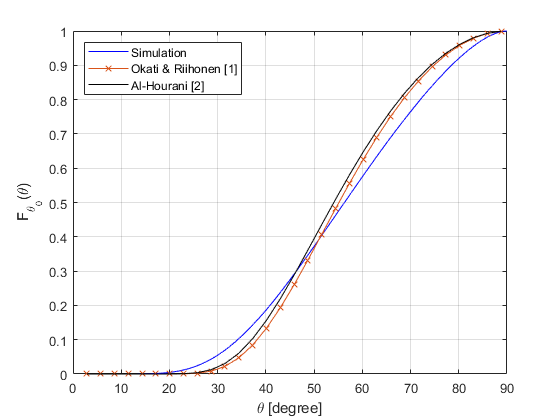


a = csvread('D:\Satellites\28GHz\data\theta0.csv');
[y,x] = hist(a, 30);
y = y/sum(y);

[y1, x1] = ecdf(a);
y = y/sum(y);




figure;
plot(x1, y1, 'b-')
hold on
plot(rad2deg(angle_vec), G_okati, 'x-')
plot(rad2deg(angle_vec), G_hourani, 'k-')

legend('Simulation', 'Okati & Riihonen [1]', 'Al-Hourani [2]', 'Location',"northwest")
xlabel('\theta [degree]')
ylabel('F_{\theta_0}(\theta)')

xlim([0 90])
ylim([0 1])
grid on;
box on;

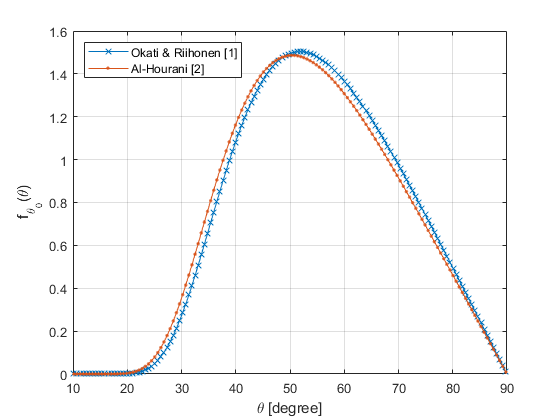

figure
hold on
plot(rad2deg([deg2rad(5): 0.01: pi/2]), g_okati([deg2rad(5): 0.01: pi/2]), 'x-')
plot( rad2deg([deg2rad(5): 0.01: pi/2]), g_hourani([deg2rad(5): 0.01: pi/2]), '.-')
xlabel('\theta [degree]')
ylabel('f_{\theta_0}(\theta)')
legend('Okati & Riihonen [1]', 'Al-Hourani [2]', 'Location',"northwest")
xlim([10, 90])
box on;
grid on;